% FFT noodling around

clc
clearvars
format shortG


## **paths and filenames**


%audiopath = 'C:\Users\jamie\Desktop\';
audiopath = '';
audio_bees = 'Audio_192k16b_12min_in_for_2min.wav';
sound_effects = 'Cheers_48k_5min.wav';
audio_squarewave_2k = 'squarewave_2k.wav';
audio_sinewave_2k = 'sinewave_2k.wav';

source = audio_bees;
audiosource = strcat(audiopath, source);

%[X, Fs] = audioread(audiosource);
% generate two sinewaves at 50Hz and 120Hz
%S = 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);
% make some noise
%X = S + 2*randn(size(t));
%n = 2^nextpow2(size(X,1));
%n = 4096;

## read data

[signal,Fs] = audioread(audiosource);

[sampleCount,channels] = size(signal);


## **FFT parameters**

%Fs = 192000;                   % fixed sampling frequency
%NFFT = 2048;                   % fixed frame size
%binwidth = 100                  % bin width in hertz
numbins = 100

numbins =    100


NFFT = 2^nextpow2(Fs/numbins);  % calc frame size
OVERLAP = 0.75;

T = 1/Fs;                       % sampling period
L = 1500;                       % length of signal (msec)
t = (0:L-1)*T;                  % time vector

spectrogram_dB_scale = 80;      % dB scale range

## Resample or decimate

nth order Chebychev IIR (cheb1) or nth order Hamming FIR (fir1)

degree = 8;     % < 2 = bypass
type = 3;       % 1 = IIR, 2 = FIR, 3 = resample (FIR)
order = 12;

%downsignal = zeros((sampleCount*2),channels);

if degree > 1
    if type == 1        % cheb IIR
        for ch = 1:channels
            downsignal(:,ch) = decimate(signal(:,ch),degree,order);
        end
    elseif type == 2    % Hamming FIR
        for ch = 1:channels
            downsignal(:,ch) = decimate(signal(:,ch),degree,order,'fir');
        end
    elseif type == 3    % FIR
        newFs = Fs/degree;
        for ch = 1:channels
            downsignal(:,ch) = resample(signal(:,ch),newFs,Fs,order);
        end
    else
        disp('gotta stop here, need 1,2,3 to change Fs');
        a = 1/0;
    end
    Fs = Fs/degree;
    signal = downsignal;
end

samples = length(signal);
time = (0:samples-1)*1/Fs;


## **weighting dB (linear / A)**

% for audible acoustics, A-weighted may be useful
% option_w = 0 : linear spectrum (no weighting dB (L) )
% option_w = 1 : A weighted spectrum (dB (A) )

option_w = 0;

## **plot 1 : time domain plot**

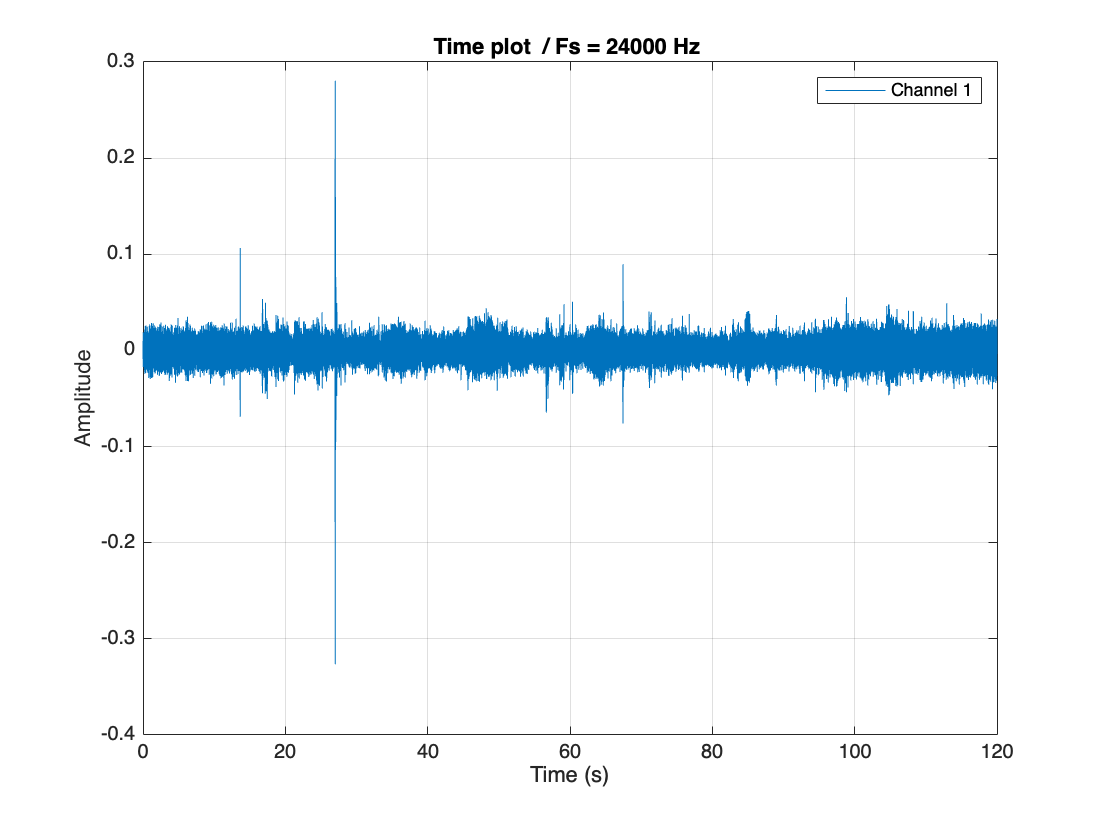

% legend 
for ch = 1:channels
    leg_str{ch} = ['Channel ' num2str(ch) ];
end

figure(1)
plot(time,signal);
grid on
title(['Time plot  / Fs = ' num2str(Fs) ' Hz ']);
xlabel('Time (s)');
ylabel('Amplitude');
legend(leg_str);

## **plot 2 : averaged FFT spectrum**

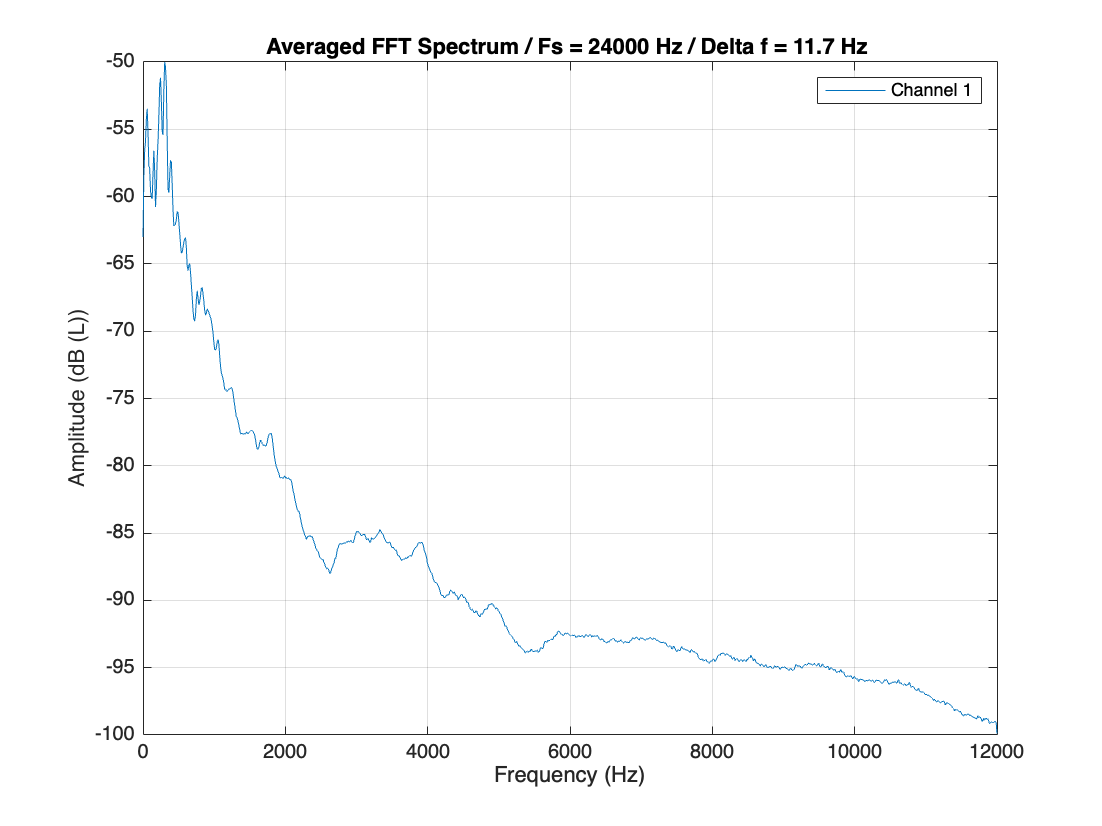


[freq, sensor_spectrum] = avgfft_peak(signal,Fs,NFFT,OVERLAP);

% convert to dB scale (ref = 1)
sensor_spectrum_dB = 20*log10(sensor_spectrum);

% apply A weigthing if selected
if option_w == 1
    pondA_dB = pondA_function(freq);
    sensor_spectrum_dB = sensor_spectrum_dB+pondA_dB;
    my_ylabel = ('Amplitude (dB (A))');
else
    my_ylabel = ('Amplitude (dB (L))');
end

figure(2),plot(freq,sensor_spectrum_dB);
grid on
df = freq(2)-freq(1);           % frequency resolution
title(['Averaged FFT Spectrum / Fs = ' num2str(Fs) ...
    ' Hz / Delta f = ' num2str(df,3) ' Hz ']);
xlabel('Frequency (Hz)');ylabel(my_ylabel);
legend(leg_str);

## **plot 3 : time / frequency analysis : spectrogram **

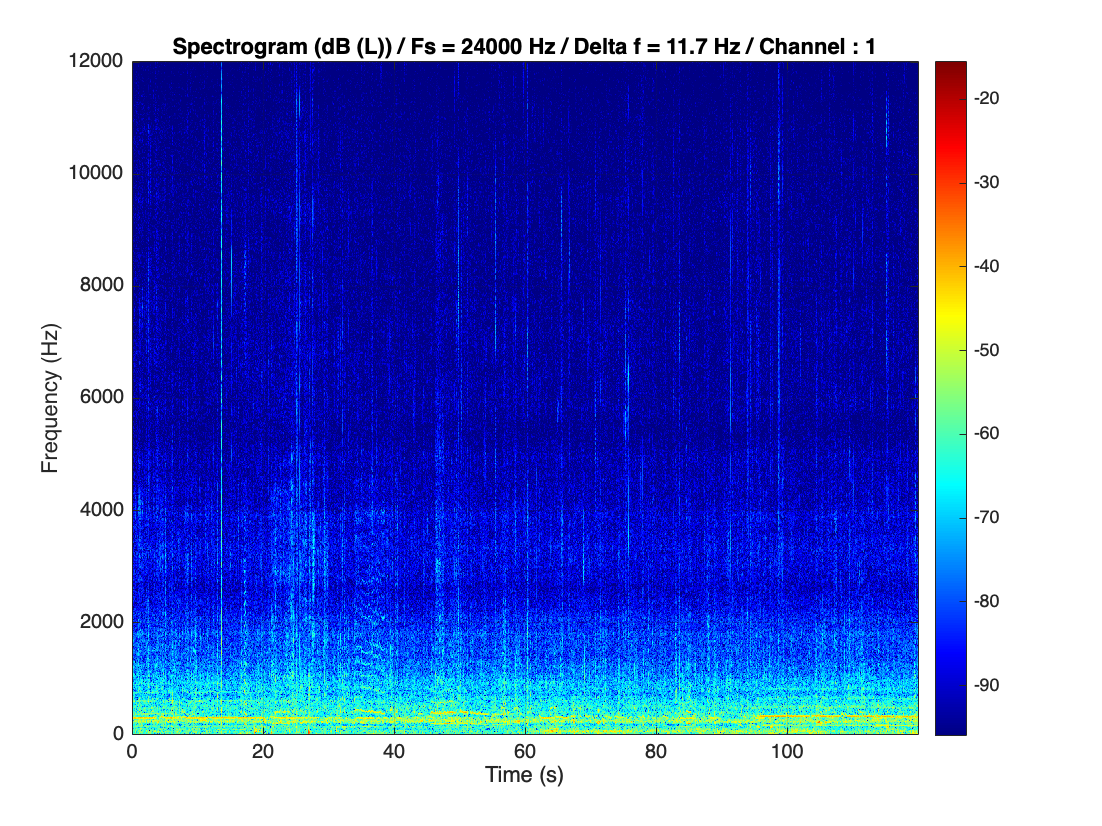


for ck = 1:channels
    [sg,fsg,tsg] = specgram(signal(:,ck),NFFT,Fs,hanning(NFFT),floor(NFFT*OVERLAP));
    
    % FFT normalisation and conversion amplitude from linear to dB (peak)
    sg_dBpeak = 20*log10(abs(sg))+20*log10(2/length(fsg));     % NB : X=fft(x.*hanning(N))*4/N; % hanning only
    
    % apply A weigthing if needed
    if option_w == 1
        pondA_dB = pondA_function(fsg);
        sg_dBpeak = sg_dBpeak+(pondA_dB*ones(1,size(sg_dBpeak,2)));
        my_title = ('Spectrogram (dB (A))');
    else
        my_title = ('Spectrogram (dB (L))');
    end
    
    % saturation of the dB range :
    % saturation_dB = 60;  % dB range scale (means , the lowest displayed level is XX dB below the max level)
    min_disp_dB = round(max(max(sg_dBpeak))) - spectrogram_dB_scale;
    sg_dBpeak(sg_dBpeak<min_disp_dB) = min_disp_dB;
    
    % plots spectrogram
    figure(2+ck);
    imagesc(tsg,fsg,sg_dBpeak);colormap('jet');
    
    % save matrix to file for comparison
    
    axis('xy');colorbar('vert');grid on
    df = fsg(2)-fsg(1); % freq resolution
    title([my_title ' / Fs = ' num2str(Fs) ' Hz / Delta f = ' num2str(df,3) ' Hz / Channel : ' num2str(ck)]);
    xlabel('Time (s)');ylabel('Frequency (Hz)');
    
end


writematrix(sg_dBpeak,'beehive_spectrogram_test_01.csv');


## **support functions**

function pondA_dB = pondA_function(f)
    % dB (A) weighting curve
    n = ((12200^2*f.^4)./((f.^2+20.6^2).*(f.^2+12200^2).*sqrt(f.^2+107.7^2).*sqrt(f.^2+737.9^2)));
    r = ((12200^2*1000.^4)./((1000.^2+20.6^2).*(1000.^2+12200^2).*sqrt(1000.^2+107.7^2).*sqrt(1000.^2+737.9^2))) * ones(size(f));
    pondA = n./r;
    pondA_dB = 20*log10(pondA(:));
end


function  [freq_vector,fft_spectrum] = avgfft_peak(signal, Fs, nfft, Overlap)
    % FFT peak spectrum of signal  (example sinus amplitude 1   = 0 dB after fft).
    % Linear averaging
    %   signal - input signal,
    %   Fs - Sampling frequency (Hz).
    %   nfft - FFT window size
    %   Overlap - buffer percentage of overlap % (between 0 and 0.95)
    
    [samples,channels] = size(signal);
    
    % fill signal with zeros if its length is lower than nfft
    if samples<nfft
        s_tmp = zeros(nfft,channels);
        s_tmp((1:samples),:) = signal;
        signal = s_tmp;
        samples = nfft;
    end
    
    % window : hanning
    window = hanning(nfft);
    window = window(:);
    
    %    compute fft with overlap
    offset = fix((1-Overlap)*nfft);
    spectnum = 1+ fix((samples-nfft)/offset); % Number of windows

    %     % for info above is equivalent to :
    %     noverlap = Overlap*nfft;
    %     spectnum = fix((samples-noverlap)/(nfft-noverlap));	% Number of windows
    
    % main loop
    fft_spectrum = 0;
    for i=1:spectnum
        start = (i-1)*offset;
        sw = signal((1+start):(start+nfft),:).*(window*ones(1,channels));
        fft_spectrum = fft_spectrum + (abs(fft(sw))*4/nfft);     % X=fft(x.*hanning(N))*4/N; % hanning only
    end
    fft_spectrum = fft_spectrum/spectnum; % to do linear averaging scaling
    
    % one sided fft spectrum, select first half
    if rem(nfft,2)                  % nfft odd
        select = (1:(nfft+1)/2)';
    else
        select = (1:nfft/2+1)';
    end
    
    fft_spectrum = fft_spectrum(select,:);
    freq_vector = (select - 1)*Fs/nfft;

end